# Modsim Project 3

*Olivia Chang and Meredith Alley*

## Question

If a penny launcher throws several pennies simulatenously at a piano from a fixed distance, at what angle and speed does each penny need to be thrown in order to play a song on the piano? i.e. such that each penny lands at a different time, in sync with the song?

**Learning Objectives: **As a result of writing this notebook, we (the authors) hope to:

- Increase understanding of optimization

- Increase understanding of physics

- Increase flexibility of code

- Use GitHub effectively

## Methodology, Part 1: The Model

### Schematic Diagram and "Movie"

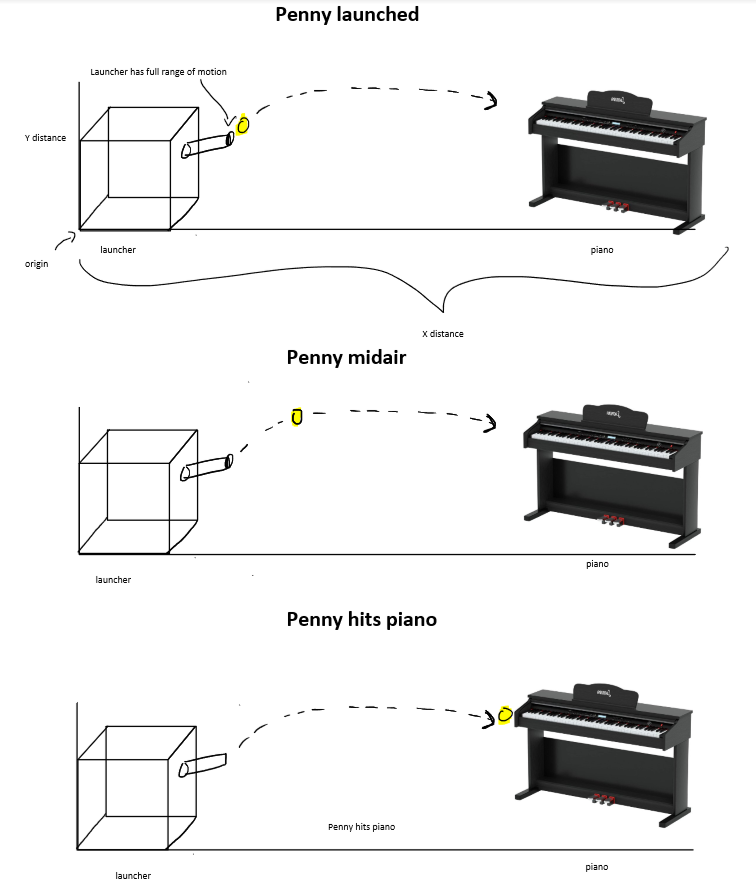

The penny launcher has multiple slots through which pennies are launched corresponding to each key (and thus note); each calibrated such that the z position of the slot is aligned with the desired key. The launcher is able to shoot multiple pennies simulatenously from the same slot at an infinitely high speed.

### Free Body Diagram

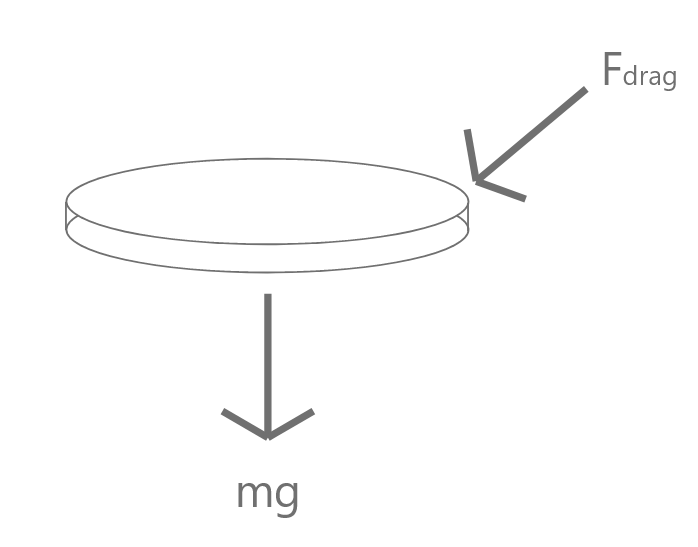

The forces affecting the penny are drag and gravity; in the y direction, the components affecting the penny are the vertical force of drag, or $\frac{Fd_y }{m}$, and gravity $F_g$,  in the x direction, the components affecting the penny are the horizontal force of drag, or $\frac{Fd_x }{m}$.

### Mathematical Model

**Parameters**

The values of area affected by drag, density, and penny weight were based on information sourced from *Drag Forces | Physics* and *Aerospaceweb.Org.*

- **Penny weight:** 2.5g

- **Penny area affected by drag:** $2\ldotp 9{*10}^{-5}$$m^2$

- **Penny density: **$7\ldotp 185{*10}^{-6} m^3$

- **X distance to piano: **1 meter. This is a rather arbitrarily chosen value, but it is also simple and additionally a realistic value for an actual penny launcher.

- **Y distance from penny launcher and piano: **for simplicity of the model, we have set up the model such that the penny launcher and piano are the same height, at 1 meter.

**2nd Order ODEs**


$$\frac{d^2 y}{dt^2 }=\frac{Fd_y }{m}-F_g$$



$$\frac{d^2 x}{dt^2 }=\frac{Fd_x }{m}$$


**1st Order ODEs**


$$\begin{array}{l}
\frac{\textrm{dy}}{\textrm{dt}}=v_y \\
\frac{{\textrm{dv}}_y }{\textrm{dt}}=\frac{Fd_y }{m}-F_g \\
\frac{\textrm{dx}}{\textrm{dt}}=v_x \\
\frac{{\textrm{dv}}_x }{\textrm{dt}}=\frac{Fd_x }{m}
\end{array}$$


### Assumptions

- The penny will always be travelling in the direction of a side, so that the face of the penny is never involved in the drag equations.

- The penny can reach impossibly high speeds: the terminal velocity of a penny is between 13.4112 m/s and 22.352 m/s. In order for the penny to land after, say, 25 seconds, and still be shot from a short distance, the penny has to be shot at speeds much greater than 22 m/s. Therefore, to make the question possible, we have assumed terminal velocity does not apply in this scenario.

- Each angle has a corresponding speed for which the penny *will* hit the piano (i.e. reach the x and y position of the piano at the same time) if launched at that angle and speed. 

- With the force of drag, there will not necessarily be an angle/speed combo that makes the penny hit the piano at the *exact* given time, but there will be one close enough that the difference is effectively nothing to the listener.

- The pennies magically disappear after hitting the keyboard. They do not bounce off the keyboard and interfere with the trajectory of the other pennies.

- The penny will hit the piano keys hard enough to actually play a note, however, even though some will hit the piano at impossibly high speeds, these piano keys are impossibly strong and will not break.

**Global Variables/Conversions**

If you don't run this, you might end up with some weird errors!

global initial_height_launcher x_distance_to_piano y_distance_to_piano;
initial_height_launcher = 1;
x_distance_to_piano = 1;
y_distance_to_piano = 0;

## Methodology, Part 2: Code Setup and Verification

tldr:

1. `ode_penny` runs the simulation, and stops the simulation when it reaches y position of piano

2. `distance_error` calculates difference in the penny's end x position - piano x position

3. `find_speed0 `uses root finding to find speed at given angle where distance error is 0 (this allows us to get corresponding speed for angle)

4. `time_error` calculates difference in actual simulation time - desired time

5. `ode_angle_and_speed` uses fminsearch to find angle/speed pair which both hits the piano and minimizes the difference between simulation time and desired time

#### ODE45 Simulation

First, we set up a simulator function called `ode_penny` that accepts a speed and angle, simulates the penny's trajectory when launched at that speed and angle. The simulation stops when the penny reaches the y position of the piano, and returns four variables: `T`, a matrix of the time steps, `M`, a matrix containing the x and y position of the penny at each time step, `did_hit_piano`, a boolean that is true if the penny hit the piano, and `end_time`, the time it took for the penny to reach the piano's y position. Note that `end_time` will be defined even if `did_hit_piano` is false.

`did_hit_piano` is used for debugging and verification purposes, and is calculated by comparing the end x position of the penny with the x position of the piano. The x position of the piano is given a buffer range which is the length of a piano key; thus, the penny hit the piano if it is between the lower and upper bounds of the x position of the piano.

Here is an example simulation with the penny launched at 30 degrees at 5 m/s.

The penny hit the piano: false
The penny took 0.50839 seconds to reach the y position of the piano.


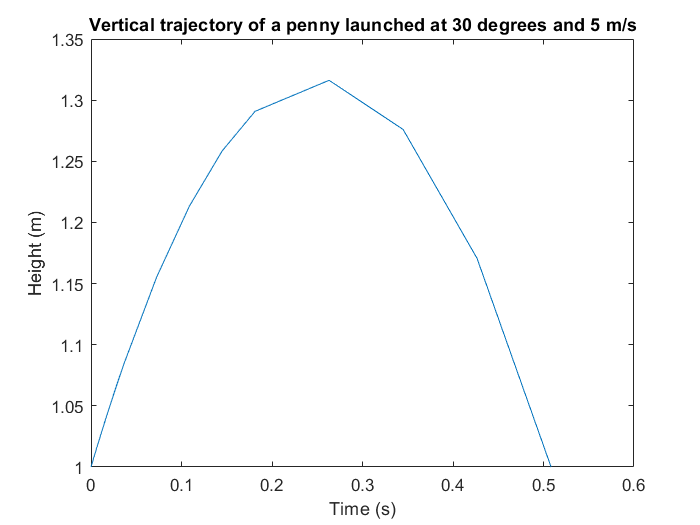

demo_speed = 5;
demo_angle = 30;
[T, M, did_hit_piano, end_time] = ode_penny(demo_speed,demo_angle);
penny_simulation_graph(T, M, did_hit_piano, end_time, demo_angle, demo_speed)

#### **Finding the corresponding speed for an angle, so that the penny hits the piano**

For every angle between 0 degrees inclusive and 90 degrees exclusive (clearly, the penny will never hit a piano that is 1 meter away if it is shot directly upwards), there will be at least corresponding speed at which the penny must be shot in order to hit the piano. Lower angles will require lower speeds, and higher angles will require higher speeds, with speeds asymptoting to infinity as the angle at which the penny is launched approaches 90 degrees.

Therefore, we created a function, `find_speed0`, that finds the corresponding speed for each angle. This function accepts an angle, and uses `fzero` to find the speed at which the `distance_error,` or the difference between the final x position of the penny and the x position of the piano, is zero. We used `fzero` rather than `fminsearch` due to the aforementioned assumption that there will be a speed for each angle where the penny will hit the piano exactly.

For example, for the angle of 30 degrees:

% find the corresponding speed for this angle
angle = 30;
initial_speed_guess = 5;
speed0 = find_speed0(angle,initial_speed_guess); % input degrees, get speed
disp("Speed at which the penny must be launched in order to hit the piano is " + speed0 + " m/s")

Speed at which the penny must be launched in order to hit the piano is 3.3745 m/s


angle_range =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90


#### **Finding which angle/speed combo hits the piano at the desired time**

Now that we can calculate the corresponding speed for each angle, we want to be able to find the angle/speed combo that will make the penny hit the piano at a given time. We have made the assumption that there will not necessarily be an angle/speed combination that gives makes the simulation `end_time` *exactly *equal to given time, but it will be close; therefore, we used `fminsearch` to find the angle combination that minimizes `time_error`, or the difference between `end_time` and the given time.

As a form of verification, `time_error` explicitly checks that the angle accepted is in between the range of 0 inclusive and 90 degrees exclusive. If it falls outside this range, then the error returned is an arbitrarily large number (rather than infinity, which confuses the minimization function that `fminsearch` uses).

An astute reader will notice that if the force of drag were ignored, then this simulation would not require the use of ODE45, as one can use basic kinematics equations to determine the speed and angle combination for the penny to hit the piano at a given time. The equations are as follows:


$$\Delta x=v_{0x} t+\frac{1}{2\;}{\mathrm{at}}^2$$


As there is no acceleration in the x direction without drag, the equation is therefore:


$$\Delta x=v_{0x} t$$


The equation in the y direction is:


$$\Delta y=v_{0y} t+\frac{1}{2\;}{\mathrm{gt}}^2$$


By plugging in the values of distance and time, we determined the approximate angle needed for a given time, and passed it to the initial guess argument in `fminsearch`; the approximate speed is passed through the `time_error` function call into the initial guess argument in `fzero`, for determining an angle's corresponding speed.

Here is an example where we want the penny to hit the piano in 5 seconds:

desired_time = 5; % seconds, time we want the penny to hit the piano
x_distance = 1;
y_distance = 0;

[initial_speed_guess, angle_guess] = get_speed_and_angle(desired_time,x_distance,y_distance);
disp("The penny should be shot at approximately " + angle_guess + " degrees at " + initial_speed_guess + " m/s")

The penny should be shot at approximately 89.5323 degrees at 24.5008 m/s


The `time_error` function accepts an angle, and first calculates the corresponding speed using `find_speed0`, and then runs the ODE simulation with the angle and the corresponding speed to get `end_time`. It then returns the difference between `end_time` and `desired_time`.

error = time_error(desired_time, initial_speed_guess, angle_guess);
disp("If the penny is shot at " + angle_guess + " degrees at " + initial_speed_guess + " m/s, then the difference between end_time and desired_time is " + error)

If the penny is shot at 89.5323 degrees at 24.5008 m/s, then the difference between end_time and desired_time is 0.38433


Then, with `fminsearch`, we can use time_error to find the angle which minimizes `time_error:`

[found_angle, found_speed, error] = ode_angle_and_speed(desired_time) % seconds

found_angle = 89.4695

found_speed = 28.2035

error = 1.3033e-04

In this context, the time error is too small to be appreciable. With the angle and speed determined, let's then run the simulation to verify that it both hits the piano and achieves the desired end time.

The penny hit the piano: true
The penny took 5.0001 seconds to reach the y position of the piano.


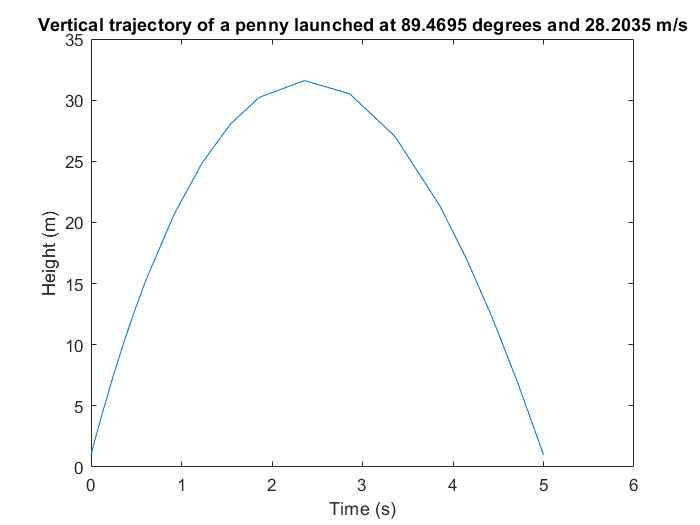

[T, M, did_hit_piano, end_time] = ode_penny(found_speed, found_angle);
penny_simulation_graph(T, M, did_hit_piano, end_time, found_angle, found_speed)

With the penny successfully hitting the piano at the given time, we can now run the simulation for each note of the song.

## Results

`notes_table` contains the time at which each penny should land in order to play the song. If we access this table, we can read both how long the note should be held (which, in a further iteration, could be used to generate the second column of times), and when the penny should land in order to play the note at the right time.

notes_table = readtable("hot_cross_buns.csv", "Delimiter", ",")

notes_table = 17×2 table
    Length    Time
    ______    ____

      2          1
      2          2
      4          3
      2          5
      2          6
      4          7
      1          9
      1        9.5
      1         10
      1       10.5
      1         11
      1       11.5
      1         12
      1       12.5
      2         13
      2         14


In order to pass this representation of the song through our functions, we first isolate the times when the penny will land and then pass them through our `ode_angle_and_speed` function, to generate our results matrix of not only the times, but also the angles and speeds at which the penny will land on the piano.

times = notes_table.Time;
for i=1:size(times)
    desired_time = times(i);
    [angle, speed] = ode_angle_and_speed(desired_time);
    angleM(i) = angle;
    speedM(i) = speed;
end

 Results = table(times,angleM',speedM','VariableNames',{'Time','Angle','Speed'})

Results = 17×3 table
    Time    Angle     Speed 
    ____    ______    ______

       1    78.391    5.0305
       2    87.011     10.03
       3    88.638    15.455
       5     89.47    28.203
       6    89.609    36.104
       7    89.695    45.574
       9     89.79     71.74
     9.5    89.804     80.48
      10    89.817    90.266
    10.5    89.827    101.61
      11    89.837    114.32
    11.5    89.846    128.97
      12    89.853    145.76
    12.5     89.86    164.93
      13    89.866    187.21
      14    89.877    241.99


As can be seen from the table, as the time value increases, the angle approaches infinity, and speed increases dramatically.

## Interpretation

The results table shows that given our infinitely powerful launcher that can shoot pennies at incredibly precise angles and speeds, and incredibly high speeds, it is theoretically possible to play a song on the piano with a penny.

### **Validation**

We can validate the model by comparing the results from `ode_angle_and_speed` with the kinematic calculations for angle and speed that don't involve drag (previously mentioned and used as initial guesses for `fminsearch` and `fzero`, and validating that the answers for angle and speed are relatively close.

for i=1:size(times)
    desired_time = times(i);
    [speed, angle] = get_speed_and_angle(desired_time, x_distance_to_piano, y_distance_to_piano);
    angleValidate(i) = angle;
    angleDiff(i) = abs(angleM(i) - angle);
    speedValidate(i) = speed;
    speedDiff(i) = abs(speedM(i) - speed);
end

 Results = table(times,angleM',angleValidate',angleDiff',speedM',speedValidate',speedDiff','VariableNames',{'Time','Angle from ODE', 'Angle from Kinematics','Angle Diff','Speed from ODE', 'Speed from Kinematics','Speed Diff'})

Results = 17×7 table
    Time    Angle from ODE    Angle from Kinematics    Angle Diff    Speed from ODE    Speed from Kinematics    Speed Diff
    ____    ______________    _____________________    __________    ______________    _____________________    __________

       1        78.391               78.465             0.074052         5.0305                5.001             0.029508 
       2        87.011               87.079             0.068097          10.03               9.8127              0.21714 
       3        88.638               88.701             0.063072         15.455               14.704               0.7513 
       5         89.47               89.532             0.062775         28.203               24.501               3.7026 
  

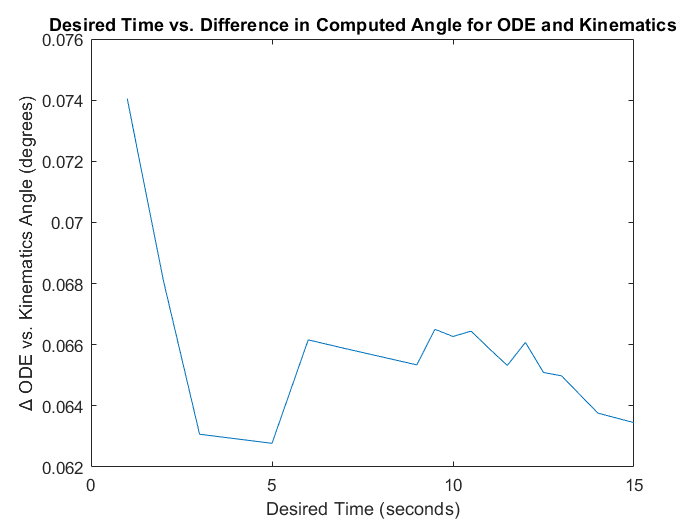

plot(times,angleDiff)
title("Desired Time vs. Difference in Computed Angle for ODE and Kinematics")
xlabel('Desired Time (seconds)')
ylabel('Δ ODE vs. Kinematics Angle (degrees)')

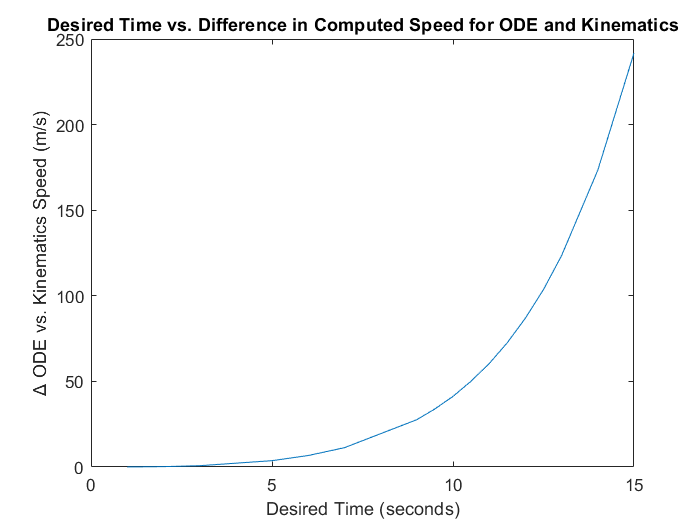

plot(times,speedDiff)
title("Desired Time vs. Difference in Computed Speed for ODE and Kinematics")
xlabel('Desired Time (seconds)')
ylabel('Δ ODE vs. Kinematics Speed (m/s)')

The difference in angle computed by `ode_penny` and the kinematics equations is very low for all time speeds. The difference in speed computed by `ode_penny` and the kinematics equations is low for small time values, and very large for the longer time values, which makes sense: the effect of drag is much greater given that the penny is in the air much longer.

### **Model Limitations and Future Development**

The model does not account for the existence of terminal velocity. If we wanted to take terminal velocity into account to be physically possible, then we would not be able to shoot all of the pennies at the same time. A future iteration of the model could shoot the pennies in batches.

Additionally, we have designed the launcher such that it has slots for each note that line up exactly with the key that we want to play; however, if one wanted to build a launcher that was instead along the short edge of the piano, and the notes were selected by varying the desired final distance for each penny, then we would build a future iteration of the model that allowed for the x distance to the piano to be an input rather than a constant, and then vary the x distance based on the distance between the launcher and the key.

For greater visualization, a future iteration of the model would also animate the actual trajectories of the pennies simulatenously, and then play the note when it reaches the penny.

## Sources

*Aerospaceweb.Org | Ask Us - Gravity, Acceleration & Speed*. http://www.aerospaceweb.org/question/dynamics/q0203.shtml. Accessed 6 Dec. 2021.

*Drag Forces | Physics*. https://courses.lumenlearning.com/physics/chapter/5-2-drag-forces/. Accessed 6 Dec. 2021.